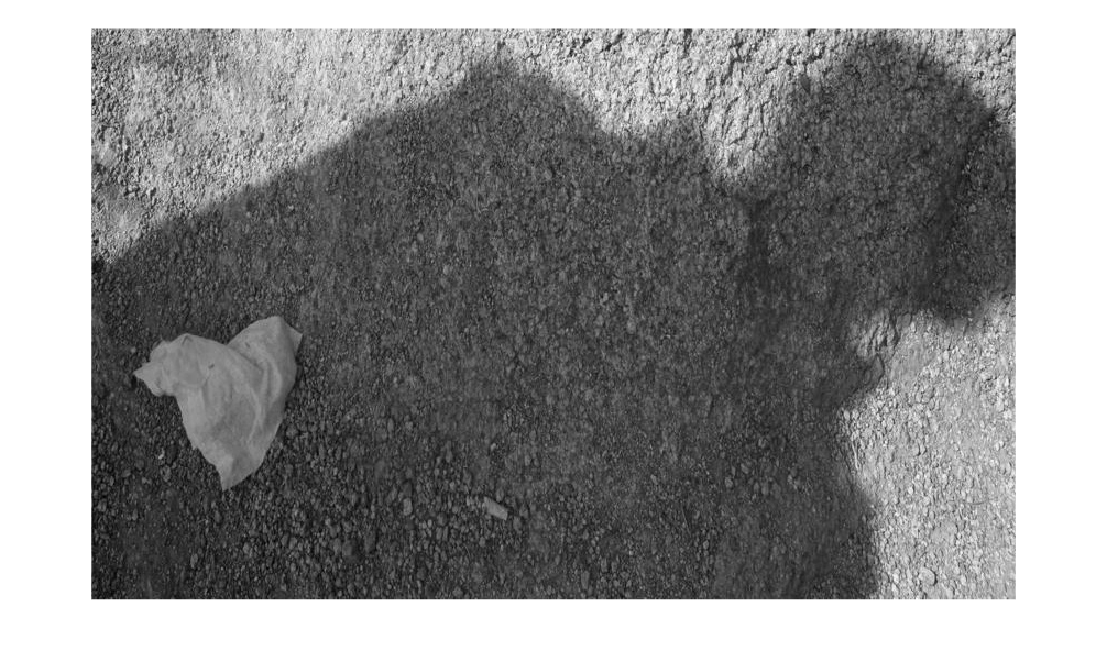

% ---- 阴影检测 ----
% 读取原始图像和生成初始掩码
ratio = 0;
radius = 2;
radius_dilate = 1;
radius_erode = 1;  % 用于腐蚀的半径
or_img = imread('CS270-Digitial-Image-Processing\project\dataset\shadow_crop/_MG_2923.jpg');
y_cb_cr_img = rgb2ycbcr(or_img);
y_channel = y_cb_cr_img(:, :, 1); 
imshow(y_channel,[]);

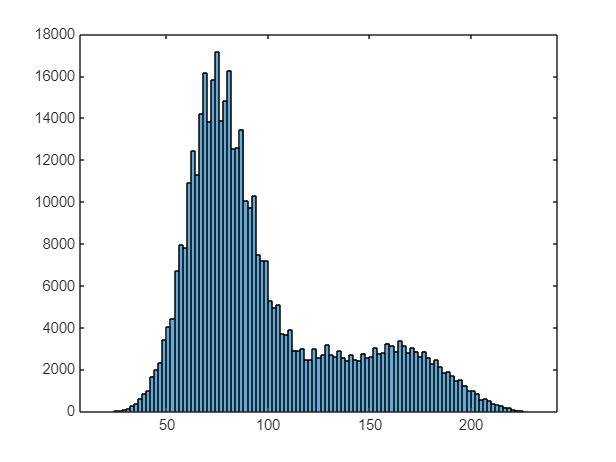

figure;
y_histogram = histogram(y_channel);

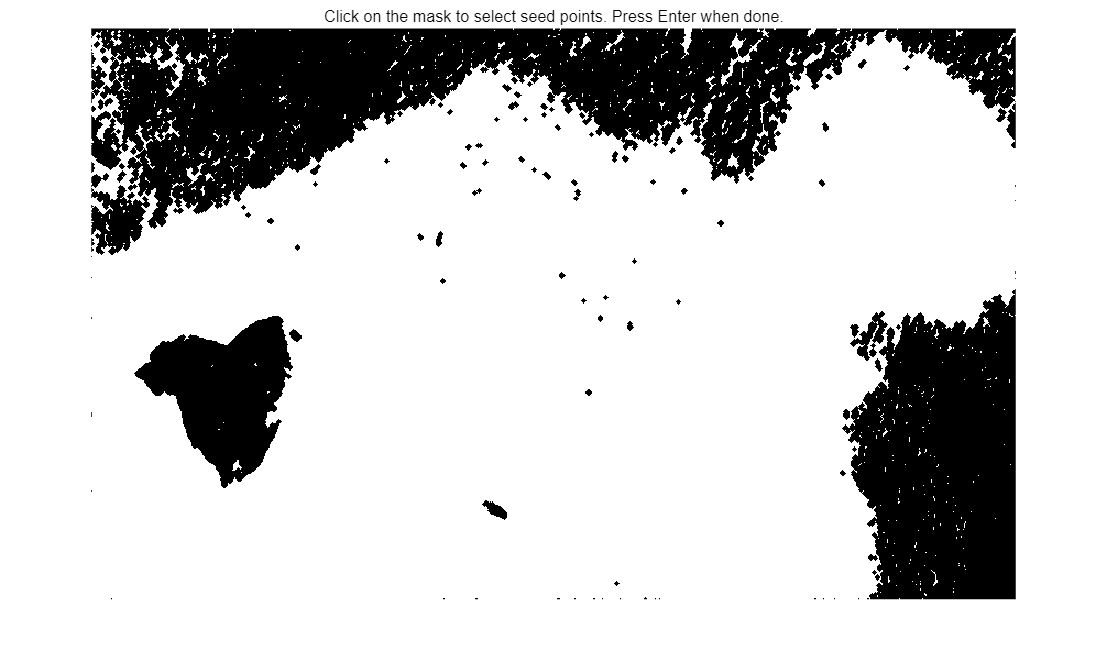

y_mean = mean(y_channel(:));
y_std = std(double(y_channel(:)));
%threshold = y_mean- (y_std / ratio);
threshold = y_mean;
shadow_mask = y_channel < threshold;
se1 = strel('disk', radius); 
%open_mask = imopen(shadow_mask, se1); 
open_mask = imclose(shadow_mask,se1);

% 显示初始掩码并提示用户选择点
figure;
imshow(open_mask, []);
title('Click on the mask to select seed points. Press Enter when done.');
hold on;

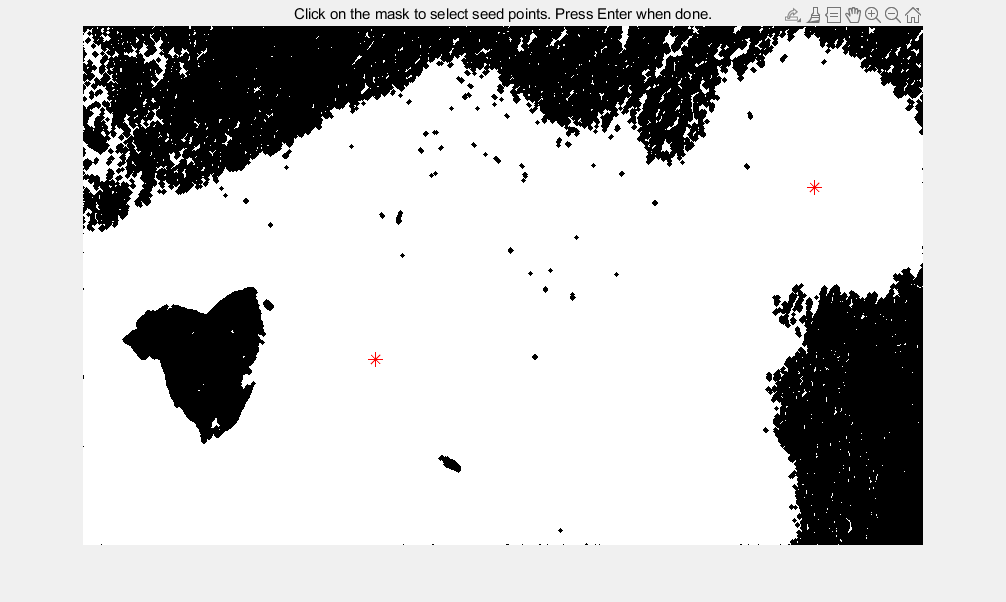


% 交互式获取用户点击的基础点
[x, y] = ginput();  % 用户点击坐标
x = round(x);       % 转换为整数索引
y = round(y);

% 验证用户选择的点是否在图像范围内
[h, w] = size(open_mask);
valid_points = (x > 0 & x <= w) & (y > 0 & y <= h);
x = x(valid_points);
y = y(valid_points);

% 在图像上标记用户选择的基础点
plot(x, y, 'r*', 'MarkerSize', 10);

final_mask = false(size(open_mask));

% 区域增长
se = strel('disk', radius_dilate);
for i = 1:length(x)
    seed = false(size(open_mask)); 
    seed(y(i), x(i)) = true;          % 设置基础点为种子
    region = seed;
    % 扩张，直到区域稳定
    while true
        dilated = imdilate(region, se);    
        new_region = dilated & open_mask; 
        if isequal(new_region, region)     % 如果区域没有变化，则退出
            break;
        end
        region = new_region;               % 更新区域
    end
    final_mask = final_mask | region;
end

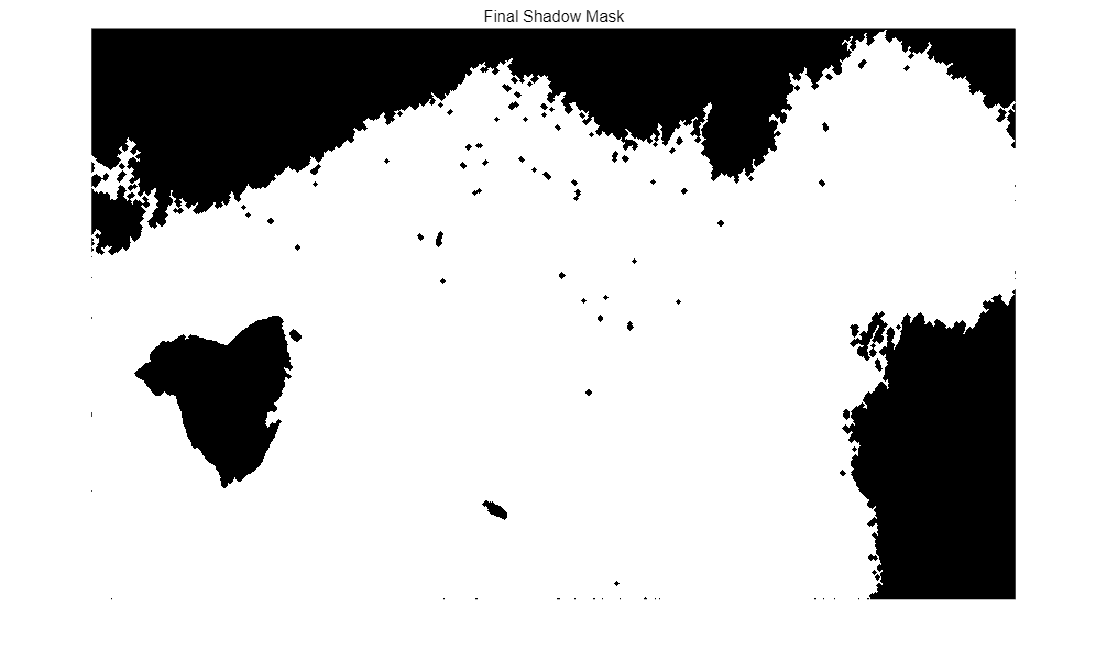

figure;
imshow(final_mask, []);
title('Final Shadow Mask');

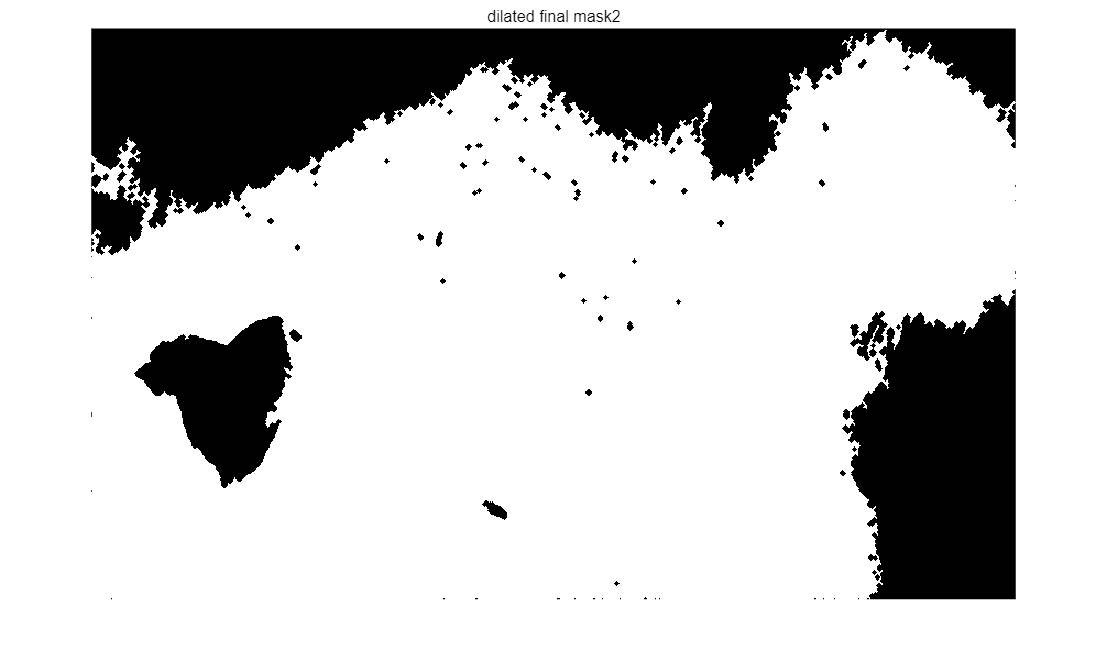

% 膨胀腐蚀
figure;
se2 = strel('disk',100); 
final_mask2 = imclose(final_mask,se1);
imshow(final_mask2, []);
title('dilated final mask2');

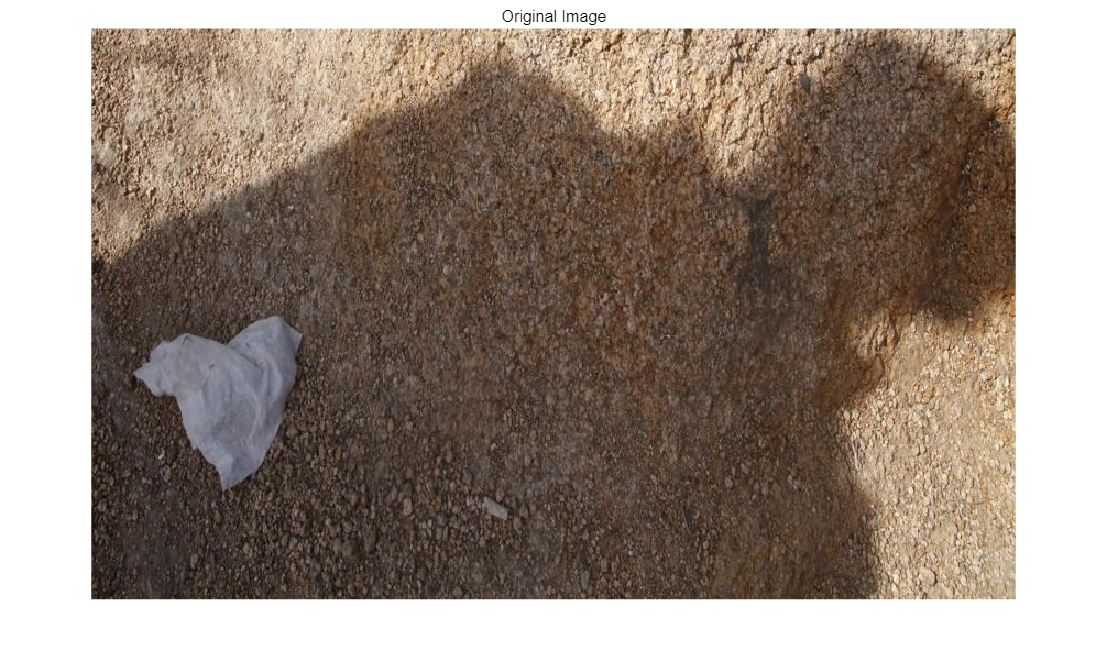


% ---- 阴影去除 ----
% 提取亮区和阴影区
shadow_region = final_mask;  % 阴影区
lit_region = ~final_mask;    % 非阴影区

% 进行掩膜腐蚀操作以提取边界
se_erode = strel('disk', radius_erode);
eroded_mask = imerode(final_mask, se_erode); % 腐蚀操作
boundary_region = final_mask & ~eroded_mask;    % 获取阴影边界

% 初始化去阴影图像（复制原始图像用于修改阴影区域）
corrected_img = double(or_img);

% 对 R, G, B 三个通道分别处理
for k = 1:3  % k = 1, 2, 3 分别对应 R, G, B
    % 当前通道的阴影和亮区像素
    shadow_pixels = double(or_img(:, :, k)) .* shadow_region;
    lit_pixels = double(or_img(:, :, k)) .* lit_region;

    % 计算阴影区域和亮区的均值与标准差
    shadow_mean = mean(shadow_pixels(shadow_pixels > 0));
    lit_mean = mean(lit_pixels(lit_pixels > 0));
    shadow_std = std(shadow_pixels(shadow_pixels > 0));
    lit_std = std(lit_pixels(lit_pixels > 0));

    % 计算通道的 alpha_k 和 gamma_k
    gamma_k = lit_std / shadow_std;
    alpha_k = lit_mean - gamma_k * shadow_mean;

    shadow_indices = find(shadow_region);  % 获取阴影区域的线性索引
    corrected_channel = corrected_img(:, :, k); % 当前通道
    corrected_channel(shadow_indices) = alpha_k + gamma_k * corrected_channel(shadow_indices);
    corrected_img(:, :, k) = corrected_channel;

    boundary_pixels = double(or_img(:, :, k)) .* boundary_region;  % 仅边界区域
    lit_pixels = double(or_img(:, :, k)) .* lit_region;  % 非阴影区域
    shadow_pixels = double(or_img(:, :, k)) .* shadow_region;  % 阴影区域
    
    %imshow(boundary_pixels,[]);
    %imshow(boundary_region,[]);
    % boundary_pixels 图像阴影边界区域的像素
    % boundary_region 图像阴影边界区域的二进制掩膜 


    % 对边界区域应用平滑
    boundary_indices = find(boundary_region);
    %corrected_channel(boundary_indices) = corrected_channel(boundary_indices);%在这应用改变

    %se = strel('disk',1);
    %dilated_boundary = imdilate(boundary_region,se);

    % gaussian blur
    sigma = 3;
    h = fspecial('gaussian',6*sigma-1,sigma);
    smooth_region = imfilter(corrected_channel,h,"replicate");
    % med
    %smooth_region = medfilt2(corrected_channel,[10 10]);
    corrected_channel(boundary_indices) = smooth_region(boundary_indices);
    corrected_img(:, :, k) = corrected_channel;
end

% 限制像素值范围 [0, 255]
corrected_img = uint8(min(max(corrected_img, 0), 255));

% 显示阴影去除结果
figure;
imshow(or_img);
title("Original Image");

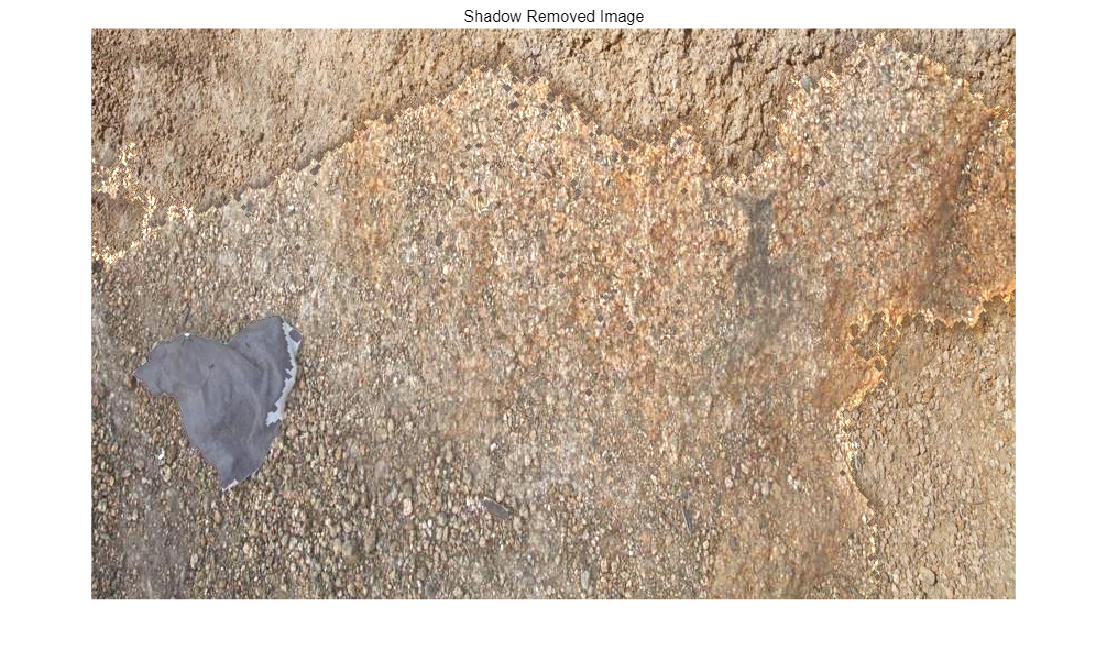

figure;
imshow(corrected_img);
title('Shadow Removed Image');